clear
conv = [pi/180, pi/180, 1];

Group = load('Original groups\GT_Vol_1_Slice_1_5.mat');
Group = Group.Group;
True_pos = cellfun(@(x) x(:, 2:4), Group, 'UniformOutput', false);
True_pos = cellfun(@(x) round(x(:, 1:3).*conv*(10^8))/(10^8), True_pos, 'UniformOutput', false);

% Collecting galaxies from Eke_fof into EGs
Eke_fof = readtable("FOF_Eke\FOF_1_1.csv");
grp_id = unique(Eke_fof(:, 'GroupID'), 'stable');
EG_eke = cell(height(grp_id), 1);
temp = 1;
for k = 1:length(EG_eke)
    idx = find(table2array(Eke_fof(:, 'GroupID')) == table2array(grp_id(k, "GroupID")));
    % only considering EG with atleast 4 members
    if length(idx) > 3
        EG_eke{temp} = Eke_fof(idx, :);
        temp = temp + 1;
    end
end
% remove the empty cells
EG_eke = EG_eke(~cellfun('isempty', EG_eke'));
EG_eke_pos = cellfun(@(x) table2array(x(:, 3:5)), EG_eke, 'UniformOutput', false);
EG_eke_pos = cellfun(@(x) round(x(:, 1:3).*conv*(10^8))/(10^8), EG_eke_pos, 'UniformOutput', false);
% Note: Eke_fof -> table of all galxies, EG_eke -> cell of EGs

% Collecting galaxies from Gama_fof into EGs
Gama_fof = load("Gama_FOF\GAMA_FOF_1_Slice_1.mat");
Gama_fof = Gama_fof.Group;
Gama_fof_pos = cellfun(@(x) x(:, 2:4), Gama_fof, 'UniformOutput', false);
Gama_fof_pos = cellfun(@(x) round(x(:, 1:3).*conv*(10^8))/(10^8), Gama_fof_pos, 'UniformOutput', false);
% Gama_fof -> Cell of EGs

% Collecting galaxies from Hough into EGs
Hough = load("Hough2\G_V_paperAll_Vol_1_S_1.mat");
Hough_pos = Hough.New_set;
Hough_mass = Hough.mass_no_final;
Hough_grpid = Hough.Group_Index;
Hough_pos = cellfun(@(x) round(x(:, 1:3).*conv*(10^8))/(10^8), Hough_pos, 'UniformOutput', false);

load("Linked_TG_and_EG.mat")

## Completeness

completeness_eke = zeros(length(Group), 3);
completeness_gama = zeros(length(Group), 3);
completeness_hough = zeros(length(Group), 3);
% Eke fof
for k = 1:length(Group)
    % Case 1
    check_detected = cellfun(@(x) ismember(True_pos{k}, x, 'rows'), EG_eke_pos, 'UniformOutput', false);
    temp = cellfun(@(x) find(x == 1), check_detected, 'UniformOutput', false);
    loopidx = find(~cellfun(@isempty, temp));
    sum = 0;
    for j = loopidx'
        sum = sum + length(temp{j});
    end
    completeness_eke(k, 1) = sum / length(Group{k}(:, 1));

    % Case 2
    assoc_eke = find(Eke_link(:, 1) == k);
    clearvars check_detected temp
    check_detected = 0;
    for j = assoc_eke'
        temp = ismember(True_pos{k}, EG_eke_pos{j}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    completeness_eke(k, 2) = check_detected / length(Group{k}(:, 1));

    % Case 3
    primary_EG = cell2mat(table2array(TG_link(k, "eke")));
    check_detected = 0;
    if primary_EG ~= 0
        temp = ismember(True_pos{k}, EG_eke_pos{primary_EG}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    completeness_eke(k, 3) = check_detected / length(Group{k}(:, 1));
end

% Gama fof
for k = 1:length(Group)
    % Case 1
    check_detected = cellfun(@(x) ismember(True_pos{k}, x, 'rows'), Gama_fof_pos, 'UniformOutput', false);
    temp = cellfun(@(x) find(x == 1), check_detected, 'UniformOutput', false);
    loopidx = find(~cellfun(@isempty, temp));
    sum = 0;
    for j = loopidx
        sum = sum + length(temp{j});
    end
    completeness_gama(k, 1) = sum / length(Group{k}(:, 1));

    % Case 2
    assoc_gama = find(Gama_link(:, 1) == k);
    clearvars check_detected temp
    check_detected = 0;
    for j = assoc_gama'
        temp = ismember(True_pos{k}, Gama_fof_pos{j}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    completeness_gama(k, 2) = check_detected / length(Group{k}(:, 1));

    % Case 3
    primary_EG = cell2mat(table2array(TG_link(k, "gama")));
    check_detected = 0;
    if primary_EG ~= 0
        temp = ismember(True_pos{k}, Gama_fof_pos{primary_EG}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    completeness_gama(k, 3) = check_detected / length(Group{k}(:, 1));
end

% Hough
for k = 1:length(Group)
    % Case 1
    check_detected = cellfun(@(x) ismember(True_pos{k}, x, 'rows'), Hough_pos, 'UniformOutput', false);
    temp = cellfun(@(x) find(x == 1), check_detected, 'UniformOutput', false);
    loopidx = find(~cellfun(@isempty, temp));
    gals = [];
    for j = loopidx
        gals = [gals; temp{j}];
    end
    gals = unique(gals);
    completeness_hough(k, 1) = length(gals) / length(Group{k}(:, 1));

    % Case 2
    assoc_hough = find(Hough_link(:, 1) == k);
    clearvars check_detected temp
    check_detected = [];
    for j = assoc_hough'
        temp = ismember(True_pos{k}, Hough_pos{j}, 'rows');
        check_detected = [check_detected; find(temp == 1)];
    end
    check_detected = unique(check_detected);
    completeness_hough(k, 2) = length(check_detected) / length(Group{k}(:, 1));

    % Case 3
    primary_EG = cell2mat(table2array(TG_link(k, "hough")));
    check_detected = [];
    if primary_EG ~= 0
        temp = ismember(True_pos{k}, Hough_pos{primary_EG}, 'rows');
        check_detected = [check_detected; find(temp == 1)];
    end
    completeness_hough(k, 3) = length(check_detected) / length(Group{k}(:, 1));
end

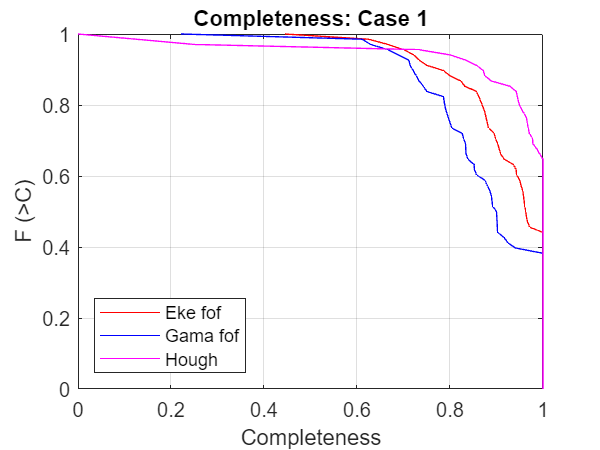

[cdf_eke, x_eke] = ecdf(1 - completeness_eke(:, 1));
[cdf_gama, x_gama] = ecdf(1 - completeness_gama(:, 1));
tem = completeness_hough(:, 1);
%tem = tem(tem <= 1);
[cdf_hough, x_hough] = ecdf(1 - tem);
p1 = plot(1 - x_eke, cdf_eke);
p1.Color = 'red';
hold on;
p2 = plot(1 - x_gama, cdf_gama);
p2.Color = 'blue';
hold on;
p3 = plot(1 - x_hough, cdf_hough);
p3.Color = 'magenta';
hold off;
grid on;
xlim([0, 1])
xlabel('Completeness')
ylabel('F (>C)')
legend(["Eke fof", "Gama fof", "Hough"], 'Location', 'southwest')
title("Completeness: Case 1")

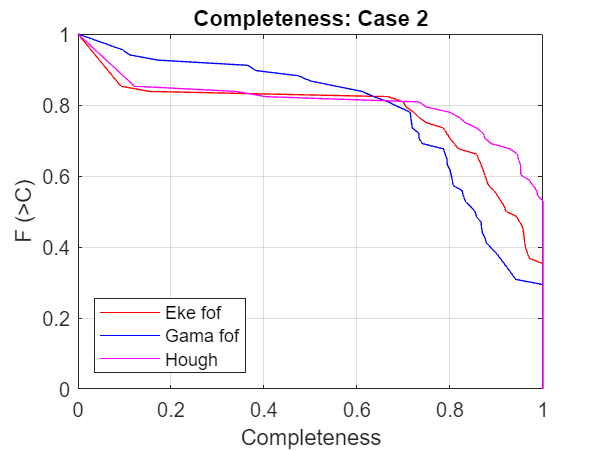

[cdf_eke, x_eke] = ecdf(1 - completeness_eke(:, 2));
[cdf_gama, x_gama] = ecdf(1 - completeness_gama(:, 2));
tem = completeness_hough(:, 2);
%tem = tem(tem <= 1);
[cdf_hough, x_hough] = ecdf(1 - tem);
p1 = plot(1 - x_eke, cdf_eke);
p1.Color = 'red';
hold on;
p2 = plot(1 - x_gama, cdf_gama);
p2.Color = 'blue';
hold on;
p3 = plot(1 - x_hough, cdf_hough);
p3.Color = 'magenta';
hold off;
grid on;
xlim([0, 1])
xlabel('Completeness')
ylabel('F (>C)')
legend(["Eke fof", "Gama fof", "Hough"], 'Location', 'southwest')
title("Completeness: Case 2")

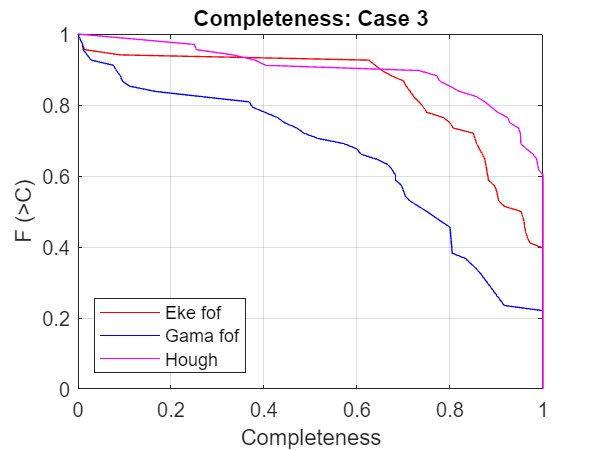

[cdf_eke, x_eke] = ecdf(1 - completeness_eke(:, 3));
[cdf_gama, x_gama] = ecdf(1 - completeness_gama(:, 3));
tem = completeness_hough(:, 3);
%tem = tem(tem <= 1);
[cdf_hough, x_hough] = ecdf(1 - tem);
p1 = plot(1 - x_eke, cdf_eke);
p1.Color = 'red';
hold on;
p2 = plot(1 - x_gama, cdf_gama);
p2.Color = 'blue';
hold on;
p3 = plot(1 - x_hough, cdf_hough);
p3.Color = 'magenta';
hold off;
grid on;
xlim([0, 1])
xlabel('Completeness')
ylabel('F (>C)')
legend(["Eke fof", "Gama fof", "Hough"], 'Location', 'southwest')
title("Completeness: Case 3")

## Reliability

reliability_eke = zeros(length(EG_eke), 3);
reliability_gama = zeros(length(Gama_fof), 3);
reliability_hough = zeros(length(Hough_grpid), 3);
TG_link_mass = cell2mat(table2array(TG_link(:, "mmg_mass")));

% Eke fof
TG_link_eke = cell2mat(table2array(TG_link(:, "eke")));
for k = 1:length(EG_eke)
    % Case 1
    check_detected = cellfun(@(x) ismember(EG_eke_pos{k}, x, 'rows'), True_pos, 'UniformOutput', false);
    temp = cellfun(@(x) find(x == 1), check_detected, 'UniformOutput', false);
    loopidx = find(~cellfun(@isempty, temp));
    sum = 0;
    for j = loopidx
        sum = sum + length(temp{j});
    end
    reliability_eke(k, 1) = sum / length(EG_eke_pos{k}(:, 1));

    % Case 2
    assoc_TG_eke = find(TG_link_eke == k);
    clearvars check_detected temp
    check_detected = 0;
    for j = assoc_TG_eke'
        temp = ismember(EG_eke_pos{k}, True_pos{j}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    reliability_eke(k, 2) = check_detected / length(EG_eke_pos{k}(:, 1));

    % Case 3
    assoc_mass = TG_link_mass(assoc_TG_eke);
    primary_TG_eke = assoc_TG_eke(assoc_mass == max(assoc_mass));
    check_detected = 0;
    if primary_TG_eke ~= 0
        temp = ismember(EG_eke_pos{k}, True_pos{primary_TG_eke}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    reliability_eke(k, 3) = check_detected / length(EG_eke_pos{k}(:, 1));
end

% Gama fof
TG_link_gama = cell2mat(table2array(TG_link(:, "gama")));
for k = 1:length(Gama_fof)
    % Case 1
    check_detected = cellfun(@(x) ismember(Gama_fof_pos{k}, x, 'rows'), True_pos, 'UniformOutput', false);
    temp = cellfun(@(x) find(x == 1), check_detected, 'UniformOutput', false);
    loopidx = find(~cellfun(@isempty, temp));
    sum = 0;
    for j = loopidx
        sum = sum + length(temp{j});
    end
    reliability_gama(k, 1) = sum / length(Gama_fof_pos{k}(:, 1));

    % Case 2
    assoc_TG_gama = find(TG_link_gama == k);
    clearvars check_detected temp
    check_detected = 0;
    for j = assoc_TG_gama'
        temp = ismember(Gama_fof_pos{k}, True_pos{j}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    reliability_gama(k, 2) = check_detected / length(Gama_fof_pos{k}(:, 1));

    % Case 3
    assoc_mass = TG_link_mass(assoc_TG_gama);
    primary_TG_gama = assoc_TG_gama(assoc_mass == max(assoc_mass));
    check_detected = 0;
    if primary_TG_gama ~= 0
        temp = ismember(Gama_fof_pos{k}, True_pos{primary_TG_gama}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    reliability_gama(k, 3) = check_detected / length(Gama_fof_pos{k}(:, 1));
end

% Hough
TG_link_hough= cell2mat(table2array(TG_link(:, "hough")));
for k = 1:length(Hough_pos)
    % Case 1
    check_detected = cellfun(@(x) ismember(Hough_pos{k}, x, 'rows'), True_pos, 'UniformOutput', false);
    temp = cellfun(@(x) find(x == 1), check_detected, 'UniformOutput', false);
    loopidx = find(~cellfun(@isempty, temp));
    sum = 0;
    for j = loopidx
        sum = sum + length(temp{j});
    end
    reliability_hough(k, 1) = sum / length(Hough_pos{k}(:, 1));

    % Case 2
    assoc_TG_hough = find(TG_link_hough == k);
    clearvars check_detected temp
    check_detected = 0;
    for j = assoc_TG_hough'
        temp = ismember(Hough_pos{k}, True_pos{j}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    reliability_hough(k, 2) = check_detected / length(Hough_pos{k}(:, 1));

    % Case 3
    assoc_mass = TG_link_mass(assoc_TG_hough);
    primary_TG_hough = assoc_TG_hough(assoc_mass == max(assoc_mass));
    check_detected = 0;
    if primary_TG_hough ~= 0
        temp = ismember(Hough_pos{k}, True_pos{primary_TG_hough}, 'rows');
        check_detected = check_detected + length(find(temp == 1));
    end
    reliability_hough(k, 3) = check_detected / length(Hough_pos{k}(:, 1));
end

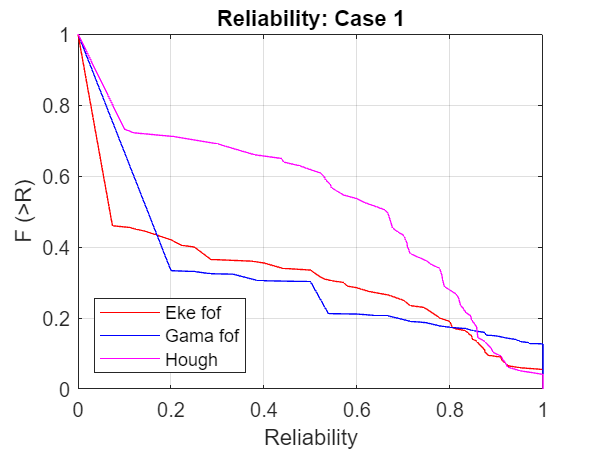

[cdf_eke, x_eke] = ecdf(1 - reliability_eke(:, 1));
[cdf_gama, x_gama] = ecdf(1 - reliability_gama(:, 1));
tem = reliability_hough(:, 1);
%tem = tem(tem <= 1);
[cdf_hough, x_hough] = ecdf(1 - tem);
p1 = plot(1 - x_eke, cdf_eke);
p1.Color = 'red';
hold on;
p2 = plot(1 - x_gama, cdf_gama);
p2.Color = 'blue';
hold on;
p3 = plot(1 - x_hough, cdf_hough);
p3.Color = 'magenta';
hold off;
grid on;
xlim([0, 1])
xlabel('Reliability')
ylabel('F (>R)')
legend(["Eke fof", "Gama fof", "Hough"], 'Location', 'southwest')
title("Reliability: Case 1")

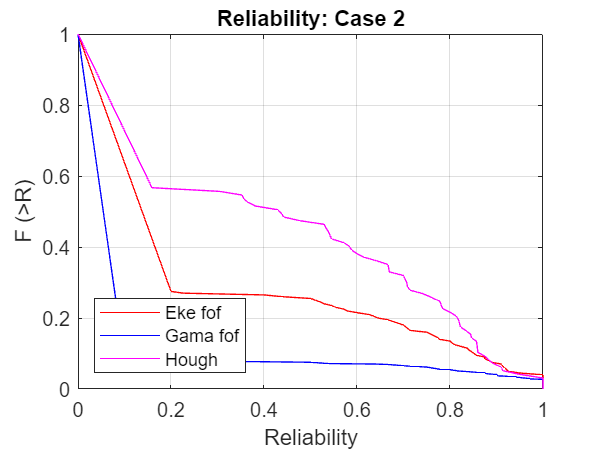

[cdf_eke, x_eke] = ecdf(1 - reliability_eke(:, 2));
[cdf_gama, x_gama] = ecdf(1 - reliability_gama(:, 2));
tem = reliability_hough(:, 2);
%tem = tem(tem <= 1);
[cdf_hough, x_hough] = ecdf(1 - tem);
p1 = plot(1 - x_eke, cdf_eke);
p1.Color = 'red';
hold on;
p2 = plot(1 - x_gama, cdf_gama);
p2.Color = 'blue';
hold on;
p3 = plot(1 - x_hough, cdf_hough);
p3.Color = 'magenta';
hold off;
grid on;
xlim([0, 1])
xlabel('Reliability')
ylabel('F (>R)')
legend(["Eke fof", "Gama fof", "Hough"], 'Location', 'southwest')
title("Reliability: Case 2")

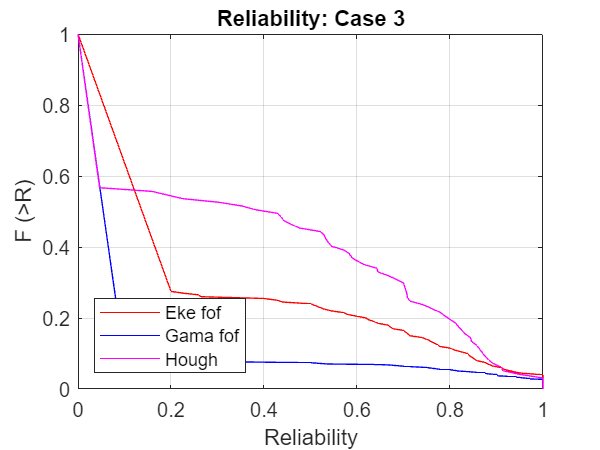

[cdf_eke, x_eke] = ecdf(1 - reliability_eke(:, 3));
[cdf_gama, x_gama] = ecdf(1 - reliability_gama(:, 3));
tem = reliability_hough(:, 3);
%tem = tem(tem <= 1);
[cdf_hough, x_hough] = ecdf(1 - tem);
p1 = plot(1 - x_eke, cdf_eke);
p1.Color = 'red';
hold on;
p2 = plot(1 - x_gama, cdf_gama);
p2.Color = 'blue';
hold on;
p3 = plot(1 - x_hough, cdf_hough);
p3.Color = 'magenta';
hold off;
grid on;
xlim([0, 1])
xlabel('Reliability')
ylabel('F (>R)')
legend(["Eke fof", "Gama fof", "Hough"], 'Location', 'southwest')
title("Reliability: Case 3")